Consider the confound of illness duration.

Mean: ratio of illness duration mean between sites

Variance: ratio of illness duration variance between sites

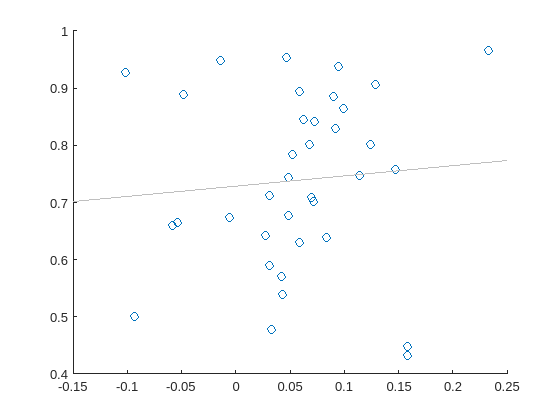

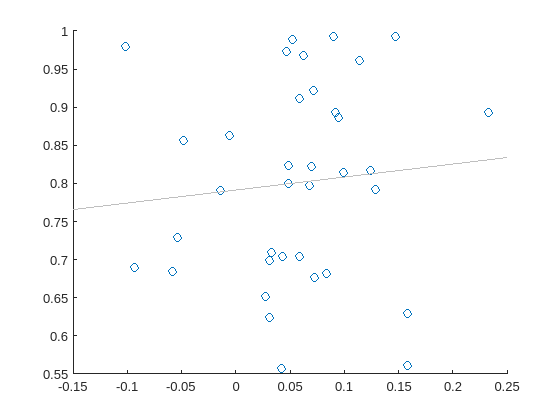

BD


                      Mean      Variance
                     _______    ________

    spearman corr    0.17477    0.18301 
    p                0.18769    0.17031 



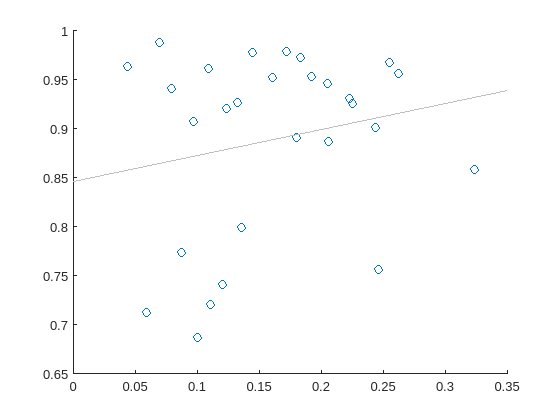

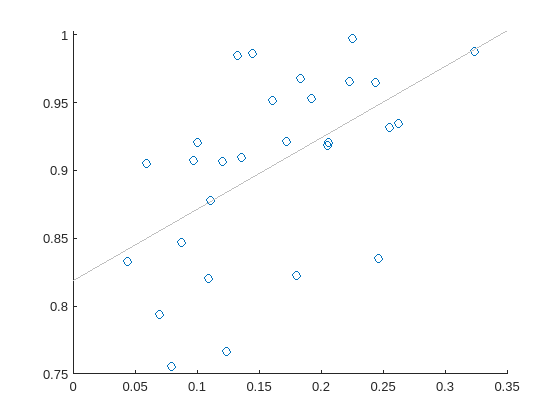

SCA


                       Mean      Variance
                     ________    ________

    spearman corr    0.090859    0.61686 
    p                 0.35559    0.01056 



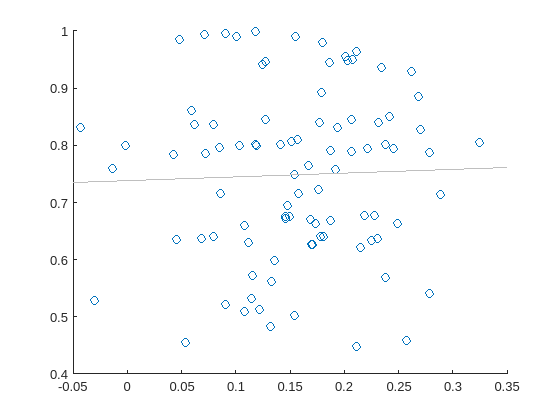

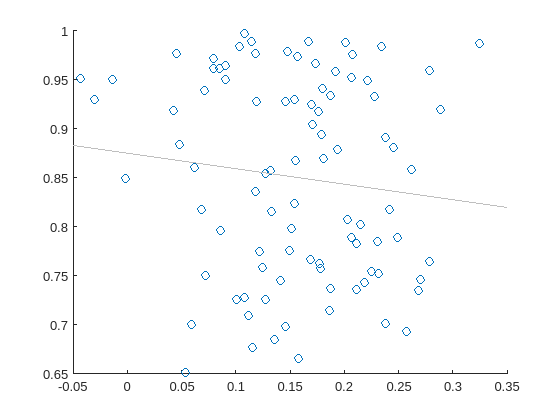

SCZ


                       Mean      Variance
                     ________    ________

    spearman corr    0.046074    -0.10379
    p                 0.34468     0.20652



ASD


MDD


AD


% Clear workspace and close all figures
clear all
close all

% Define parameters
iCOMBAT = 1; % Flag for applying COMBAT harmonization
smoothKernel = 10; % Smoothing kernel size
iter = 5000; % Number of iterations for Mantel test
hemi = 'lh'; % Hemisphere (e.g., left hemisphere)
type = 'spearman'; % Type of correlation (Spearman rank correlation)
diagnosisString = {'BD', 'SCA', 'SCZ', 'ASD', 'MDD', 'AD'}; % List of diagnoses

nDiag = length(diagnosisString); % Number of diagnoses

% Set the address path based on whether COMBAT is applied
if iCOMBAT == 1
    address = ['derivatives/s', num2str(smoothKernel), 'COMBAT/'];
else
    address = ['derivatives/s', num2str(smoothKernel), '/'];
end

% Load metadata (scanner information)
metadata = readtable(['/projects/kg98/trangc/VBM/data/metadataSBM_extended.csv'], 'VariableNamingRule', 'preserve');

% Load precomputed correlation matrices and site information
load(['output/corr_zmap_combat', num2str(iCOMBAT), '_smooth', num2str(smoothKernel), '_', hemi, '_all.mat'], ...
    'map', 'corDiag', 'corSig', 'siteList');

% Initialize variables for results
varTable = cell(nDiag, 1);
nSite = cell(nDiag, 1);

% Loop through each diagnosis
for iDiag = 1:nDiag
    % Compute variance related to illness duration similarity between sites
   [varTable{iDiag}  meanIllness{iDiag}, varIllness{iDiag}, nSite{iDiag}]= cor_var_illness(metadata, diagnosisString(iDiag), corDiag{iDiag}, siteList{iDiag}, iter, type);
   
   % Display results for the current diagnosis
   if size(varTable,1)~=0
        disp(char(diagnosisString(iDiag)))
        disp(varTable{iDiag})
        disp(' ')
        disp(' ')
    end
end

% Suppress warnings related to the last operation
warning('off', 'last');

% Save results to a .mat file
save('output/confound_illnessDuration.mat','varTable','meanIllness', 'varIllness','nSite')